# Linear Systems- Lab 1

Name: Zhu Chenhao

HDU ID: 22320630

ITMO ID: 375462

Email: 22320630@hdu.edu.cn

 Case 4. Mass-Spring-Damper system with free base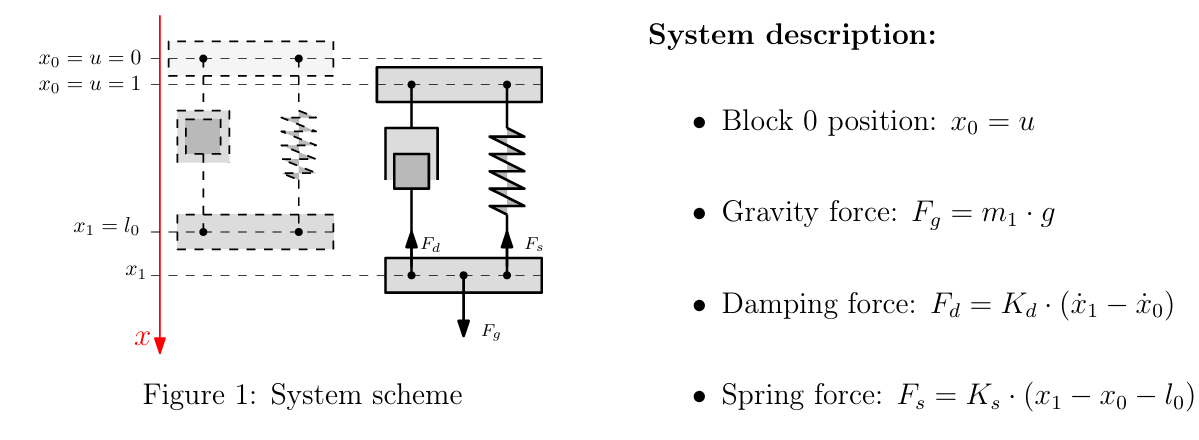

hwc = hwc_connect('https://dss2025.hdu.vedyakov.com');

Connection established


task = hwc.get_task(1);

## 0. Loading the initial data:

task.parameters;
Kd = task.parameters.Kd;
Ks = task.parameters.Ks;
g = task.parameters.g;
l0 = task.parameters.l0;
m1 = task.parameters.m1;
w = task.parameters.w;

## 1. Transfer Function:

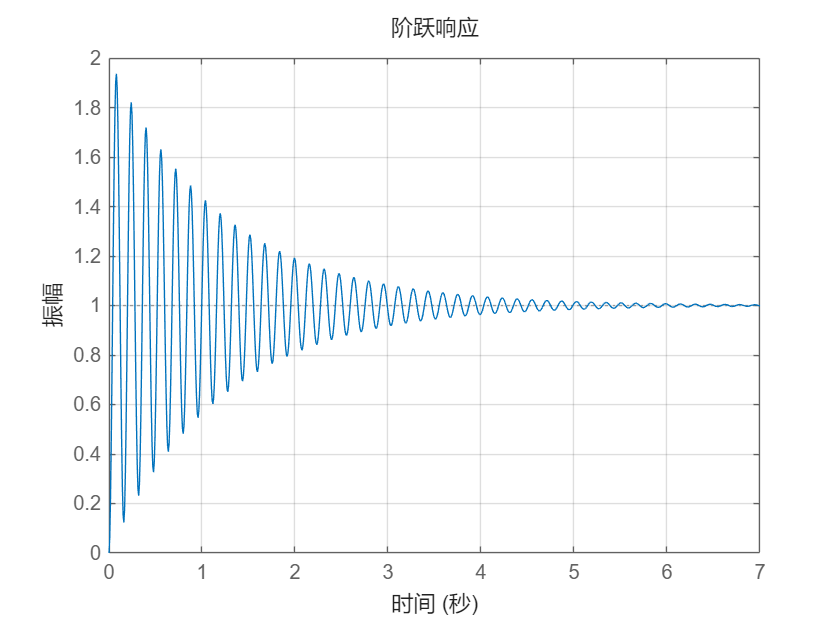

num = [Kd Ks];
deno = [m1 Kd Ks];
W = tf([num],[deno]);
[A B C D] = tf2ss(num,deno);
step(ss(A,B,C,D))
grid on;

A1 = [0 1;-Ks/m1 -Kd/m1];
B1 = [0;1/m1];
C1 = [Ks Kd];
D1 = 0;
step(ss(A1,B1,C1,D1))
grid on;

## 2. Solve differential equation using  zero initial conditions for u = 1.

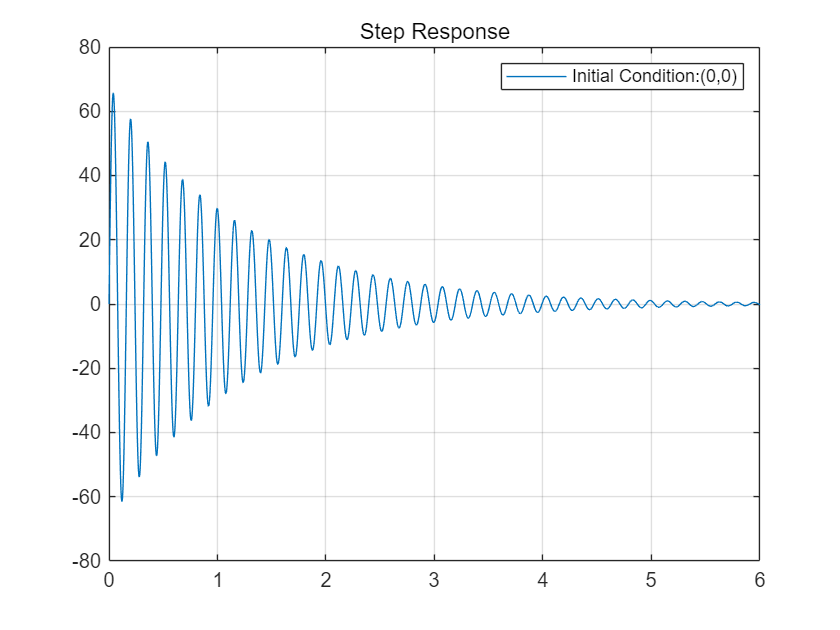

u = 1;
x0 = [0;0];
tspan = [0 6];
options = odeset('MaxStep', 1e-3);
solver = ode45(@(t,x) odefun(t,x,u,A,B,C,D), tspan, x0, options);
y = [Ks, Kd] * solver.y;
plot(solver.x, y(1,:), 'DisplayName', 'Initial Condition:(0,0)');
title('Step Response')
grid on;
legend show;

## 3. Find the equilibrium point.

- 
$$\begin{array}{l}
\frac{dx_1 }{dt}=x_2 =0\\
\frac{dx_2 }{dt}=-\frac{K_s }{m_1 }x_1 -\frac{K_d }{m_1 }x_2 +\frac{1}{m_1 }u=0
\end{array}$$


- 
$$u=0\Rightarrow x_1 =x_2 =0$$


- $x=\left\lbrack \begin{array}{cccccccccccccccccccc}
x_1 \\
x_2 
\end{array}\right\rbrack$,$x^* =\left\lbrack \begin{array}{cccccccccccccccccccc}
0\\
0
\end{array}\right\rbrack$

## 4. Use change of state coordinates v = x-x*


$$v=x-x^* =\left\lbrack \begin{array}{cccccccccccccccccccc}
x_1 \\
x_2 
\end{array}\right\rbrack$$


thus, it's the same with the step 3

## 5. New differential equationzero with initial conditions for u = 1

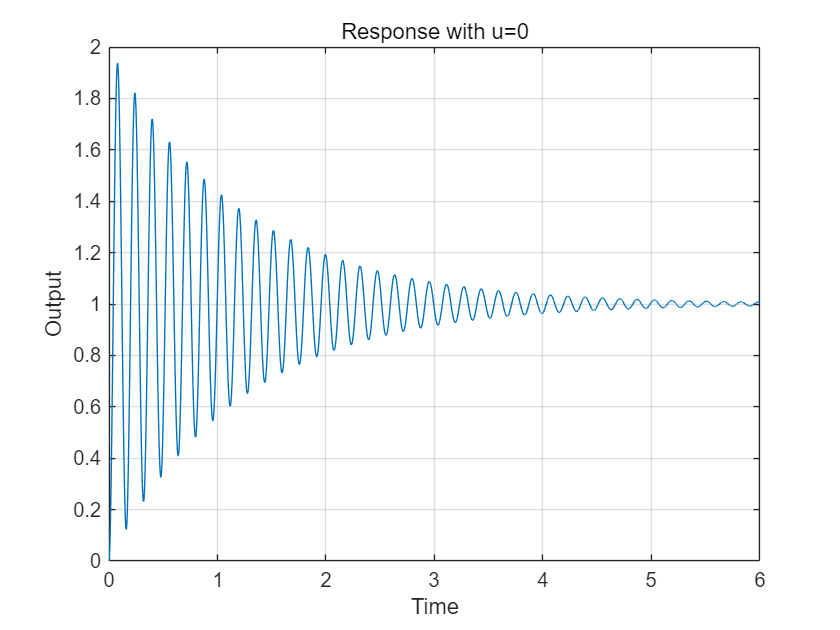

u = 1;
v0 = [0; 0];
tspan = [0 6];
options = odeset('MaxStep', 1e-3);

[t, x] = ode45(@(t,x) A*x + B*u, tspan, v0, options);
y = C * x';

figure;
plot(t, y, 'DisplayName', 'u=0, x0=[0;0]');
title('Response with u=0');
xlabel('Time');
ylabel('Output');
grid on;

## 6. Find transfer function of the system with equilibrium point v* = 0


$$\begin{array}{l}
\frac{dx_1 }{dt}=x_2 =0\\
\frac{dx_2 }{dt}=-\frac{K_s }{m_1 }x_1 -\frac{K_d }{m_1 }x_2 +\frac{1}{m_1 }u=0
\end{array}$$



$$\begin{array}{l}
s\cdot x_1 =x_2 \\
s\cdot x_2 =-\frac{K_s }{m_1 }x_1 -\frac{K_d }{m_1 }x_2 +\frac{1}{m_1 }u
\end{array}$$



$$W(s)=\frac{X_1 (s)}{U(s)}=\frac{K_d s+K_s }{m_1 s^2 +K_d s+K_s }$$


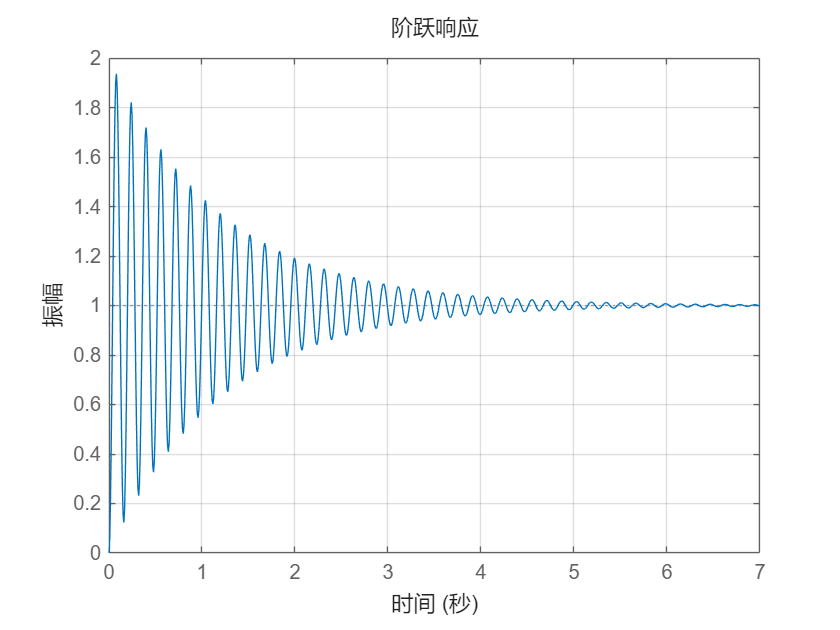

num = [Kd Ks];
deno = [m1 Kd Ks];
W = tf([num],[deno]);
[A B C D] = tf2ss(num,deno);
step(ss(A,B,C,D))
grid on;

##  7. Construct state space model

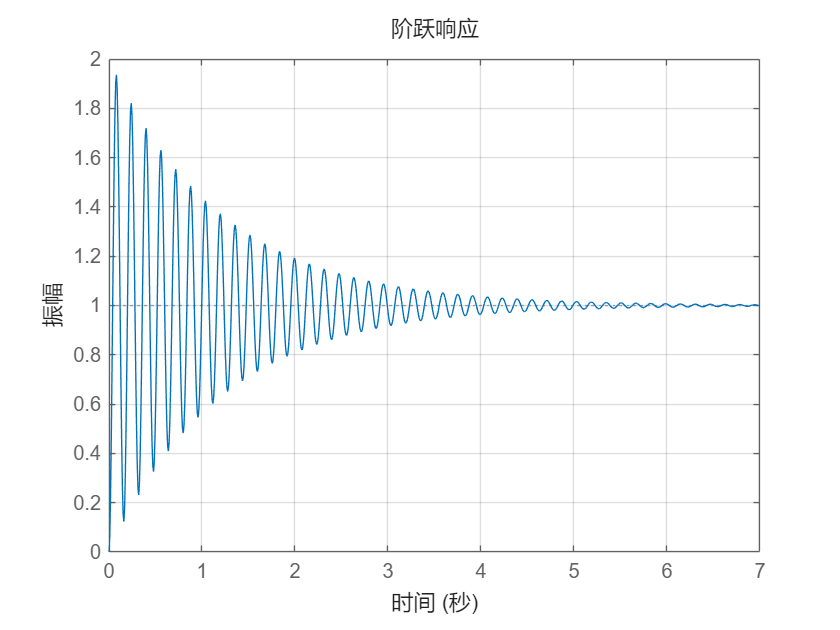

A2 = [0 1;-Ks/m1 -Kd/m1];
B2 = [0;1/m1];
C2 = [Ks Kd];
D2 = 0;
sys = ss(A2,B2,C2,D2);
step(ss(A2,B2,C2,D2))
grid on;

##  8. Plot the graphs

(a) Step response comparison & (b) Plot step response

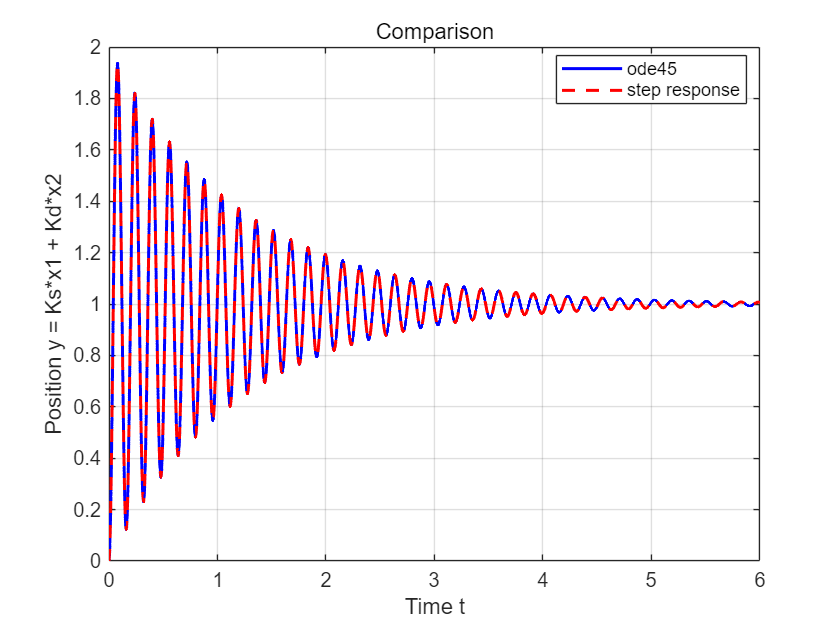

u_step = @(t) double(t >= 0);
tspan = [0 6];
x0 = [0; 0];
options = odeset('MaxStep', 1e-3);

[t_ode, x_ode] = ode45(@(t,x) A*x + B*u_step(t), tspan, x0, options);
y_ode = C*x_ode';

sys = ss(A,B,C,D);
[y_step, t_step] = step(sys, tspan(end));

figure;
plot(t_ode, y_ode, 'b-', 'LineWidth', 1.5, 'DisplayName', 'ode45');
hold on;
plot(t_step, y_step, 'r--', 'LineWidth', 1.5, 'DisplayName', 'step response');
hold off;

title('Comparison');
xlabel('Time t');
ylabel('Position y = Ks*x1 + Kd*x2');
legend('Location', 'best');
grid on;

(c) Plot phase portrait

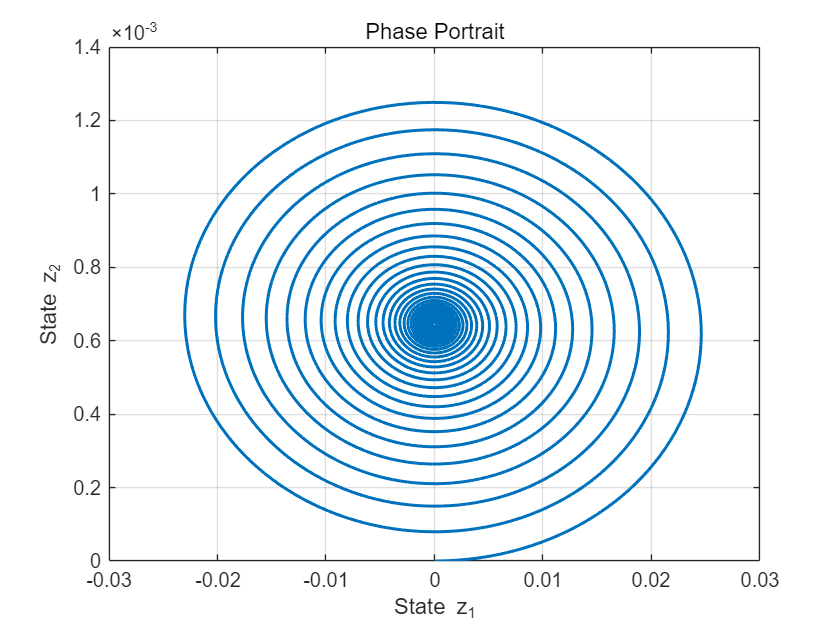

plot(solver.y(1,:), solver.y(2,:), 'LineWidth', 1.5);
xlabel('State z_1');
ylabel('State z_2');
title('Phase Portrait');
grid on;

 (d) Plot impulse response

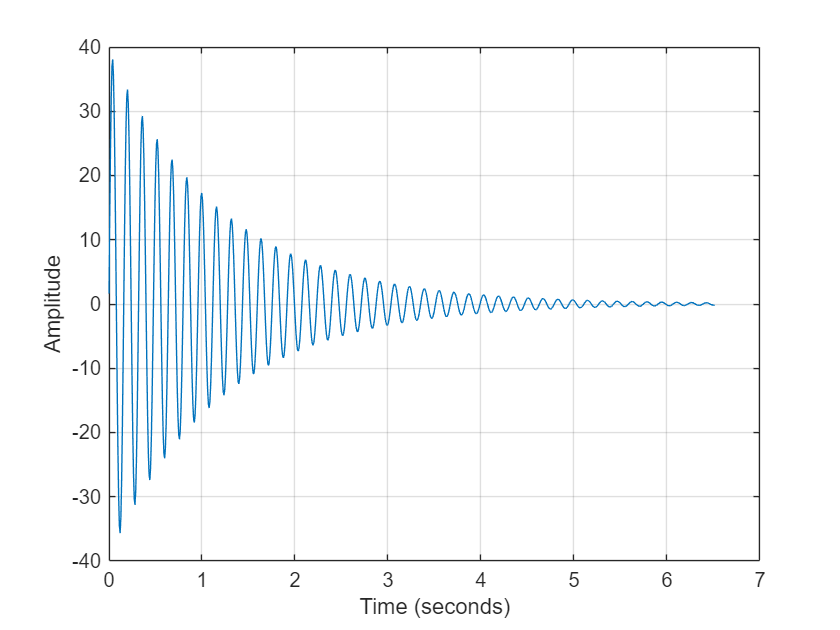

[y_imp, t_imp] = impulse(sys);
[max_imp, idx_max_imp] = max(y_imp);
figure;
plot(t_imp, y_imp);
hold on;
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

 (e) For both models plot response

tspan_sin = [0 15];
sol_sin = ode45(@(t,x) odefun(t,x,u,A,B,C,D),tspan_sin,x0);
y_sin=[Ks,Kd]*sol_sin.y;
plot(sol_sin.x, y_sin(1,:), 'DisplayName', '(0,0) Initial Condition');
hold on

[pks, locs] = findpeaks(y_sin);
[troughs,locs1] = findpeaks(-y_sin);

amplitude_changes = length(pks) + length(troughs);
plot(sol_sin.x(locs), pks, 'ro', 'DisplayName', 'Peaks');
plot(sol_sin.x(locs1), -troughs, 'bo', 'DisplayName', 'Troughs');

fprintf('The amplitude of the output signal y(t) changed %d times with respect to the input u(t) when system oscillations stabilized.\n', amplitude_changes);

The amplitude of the output signal y(t) changed 188 times with respect to the input u(t) when system oscillations stabilized.


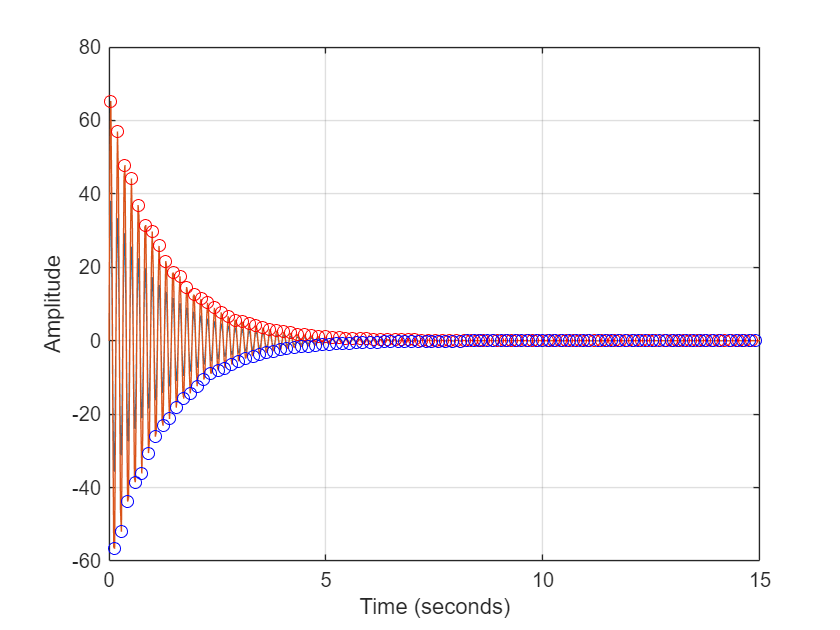

hold off;

(f) Plot Magnitude and Phase data

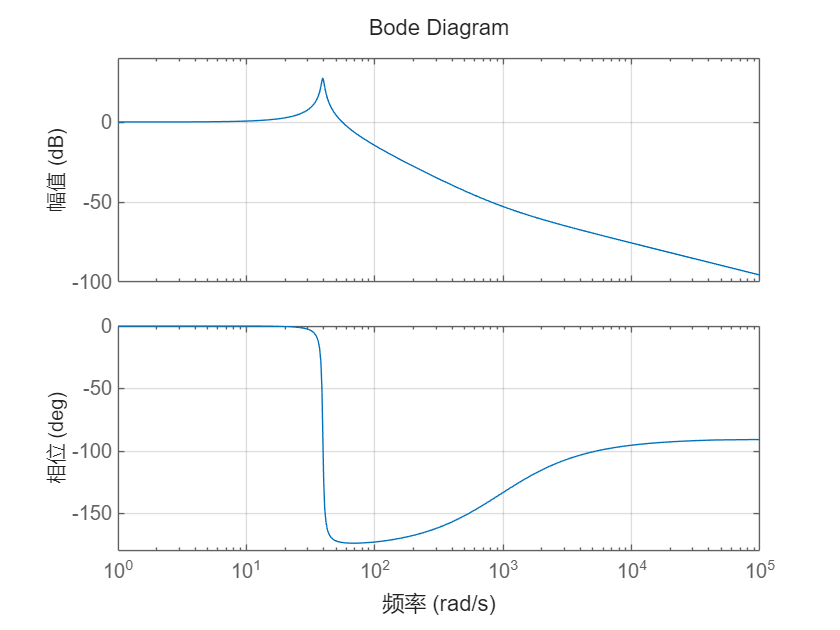

bode(sys);
title('Bode Diagram');
grid on;

Answers

sys1=ss(A,B,C,D);
info = stepinfo(sys);
[Gm,Pm,Wcg,Wcp] = margin(sys);
task.answers.Bode_Plot_Gain_crossover_frequency = 0;
task.answers.Impulse_Response_MaxTime = t_imp(idx_max_imp);
task.answers.Step_Response_Peak = info.Peak;
task.answers.Step_Response_RiseTime = info.RiseTime;

task.answers.Bode_Plot_Resonance_frequency = 39.4;
task.answers.Impulse_Response_SettlingTime = 5;
task.answers.Bode_Plot_Phase_crossover_frequency = [0 58.8];
task.answers.Bode_Plot_Peak_gain_of_resonance = 24;

task.answers

ans = 包含以下字段的 struct :
       Bode_Plot_Peak_gain_of_resonance: 24
    Bode_Plot_Phase_crossover_frequency: [0 58.8000]
          Bode_Plot_Resonance_frequency: 39.4000
          Impulse_Response_SettlingTime: 5
                 Step_Response_RiseTime: 0.0267
     Bode_Plot_Gain_crossover_frequency: 0
               Impulse_Response_MaxTime: 0.0399
                     Step_Response_Peak: 1.9363


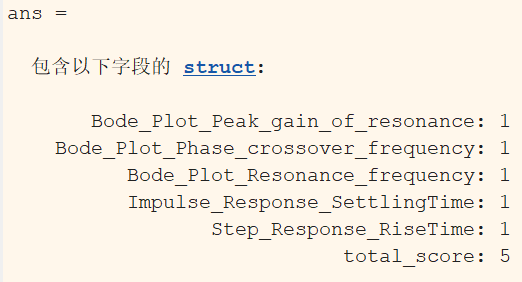

# **Function**

function dtdx = odefun(t,x,u,A,B,C,D)
    dtdx = A*x + B*u;
end


function dtdx = odefun2(t,x,A,B,C,D)
    u = sin(50 * t); 
    dtdx = A*x + B*u;
end